filename = 'P5_7.5psi.csv'; % Nombre de tu archivo CSV
startRow = 15; % Indica la fila desde la cual comenzar a leer, ajusta según haya encabezados

% Detecta las opciones de importación automáticamente y establece las líneas de datos
opts = detectImportOptions(filename, 'Delimiter', ';'); % Especificar el delimitador semicolon aquí
opts.DataLines = [startRow Inf];  % Lee desde startRow hasta el final del archivo
opts.VariableNamingRule = 'preserve';  % Conserva los nombres originales de las columnas

% Leer los datos en una tabla
T = readtable(filename, opts);

% Supongamos que T es tu tabla y tiene columnas Var1, Var2, ..., VarN
% Iterar sobre cada columna
for i = 1 : width(T)
    % Obtener los datos de la columna
    colData = T{:, i};
    
    % Verificar si los datos son un array de celdas de char (cadenas)
    if iscellstr(colData)
        % Reemplazar comas por puntos y convertir cadenas a doubles
        numericData = str2double(strrep(colData, ',', '.'));
        
        % Reemplazar la columna en la tabla con los datos numéricos
        T.(i) = numericData;
    elseif iscell(colData)  % si la celda contiene algo diferente de char (por ejemplo, array de strings)
        % Convertir array de celdas de strings (si son strings) a un array regular de strings
        colData = string(colData);
        
        % Reemplazar comas por puntos
        colData = replace(colData, ',', '.');
        
        % Convertir strings a doubles
        numericData = str2double(colData);
        
        % Reemplazar la columna en la tabla con los datos numéricos
        T{:, i} = numericData;
    end
end


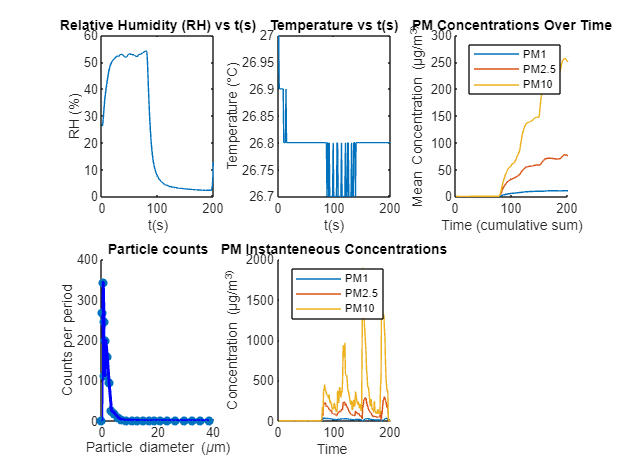


temperature = T{:, 33};
RH = T{:, 34};
t = cumsum(T{:, 31})*2.1018;

indice_inicio = find(t > 60, 1);  % Encuentra el primer índice donde t es mayor a 100


MeanPM1 = T{:, 44};
MeanPM2_5 = T{:, 45};
MeanPM10 = T{:, 46};

% Create plots
figure; % Create a new figure
subplot(2,3,1); % Create the first subplot
plot(t, RH); % Plot RH vs cumulative sum
title('Relative Humidity (RH) vs t(s)');
xlabel('t(s)');
ylabel('RH (%)');

subplot(2,3,2); % Create the second subplot
plot(t, temperature); % Plot Temperature vs cumulative sum
title('Temperature vs t(s)');
xlabel('t(s)');
ylabel('Temperature (°C)');



% Plot the data
subplot(2,3,3); % Create the second subplot
hold on; % Hold on to the current figure
plot(t, MeanPM1, 'DisplayName', 'PM1');
plot(t, MeanPM2_5, 'DisplayName', 'PM2.5');
plot(t, MeanPM10, 'DisplayName', 'PM10');
hold off;

% Add labels and title
xlabel('Time (cumulative sum)');
ylabel('Mean Concentration (μg/m^3)');
title('PM Concentrations Over Time');
legend('show'); % Show legend

% Suponiendo que estas variables ya están definidas y 'T' es una tabla o matriz existente.
particlediameter_um = [0, 0.41, 0.56, 0.83, 1.15, 1.5, 2, 2.65, 3.5, 4.6, 5.85, 7.25, 9, ...
                       11, 13, 15, 17, 19, 21, 23.5, 26.5, 29.5, 32.5, 35.5, 38.5]; % Proporcionado por el sensor

% Asumimos que 'T' es una variable existente y hemos calculado los promedios
bin = T{:, 2:25};


if ~isempty(indice_inicio)  % Verifica si se encontró un índice que cumpla la condición
    bin_filtrado = bin(indice_inicio:end, :);  % Filtrar las filas desde el índice donde t > 100
    promedios = mean(bin_filtrado, 1);    % Calcular la media de cada columna
else
    disp('No se encontró ningún valor de t mayor que 100');
end
promedios = [0, promedios];

% Definir vectores para el eje X y eje Y.
r = particlediameter_um; % Vector de datos para el eje X
m = promedios; % Vector de datos para el eje Y

subplot(2,3,4); % Create the second subplot

% Crear gráfico de dispersión
scatter(r, m, 'filled'); % 'filled' para puntos rellenos

hold on; % Mantener el gráfico actual para agregar las líneas

% Añadir las líneas rectas que unen los puntos.
plot(r, m, 'b-', 'LineWidth', 2); % Línea azul con un ancho de 2

% Opcional: Añadir etiquetas y título

xlabel('Particle diameter (\mum)');
ylabel('Counts per period');
title('Particle counts');

hold off; % Liberar el gráfico actual

PM1 = T{:, 41};
PM2_5 = T{:, 42};
PM10 = T{:, 43};
%PM10= fftfilter(PM10);

subplot(2,3,5); % Create the second subplot
hold on; % Hold on to the current figure
plot(t, PM1, 'DisplayName', 'PM1');
plot(t, PM2_5, 'DisplayName', 'PM2.5');
plot(t, PM10, 'DisplayName', 'PM10');
hold off;

% Add labels and title
xlabel('Time ');
ylabel('Concentration (μg/m^3)');
title('PM Instanteneous Concentrations');
legend('show'); % Show legend